# Cvičení 7 - B2M31AEDA

## Nahrání dat

**Důležité! **V dnešním cvičení naleznete opět na Moodle ke stažení dva data sety, data.csv a large_dataset.csv. Zopakujete si princip vyšetření potřebné velikosti vzorku, který jste se naučili minule.

## ČTĚTE POZORNĚ ZADÁNÍ!!! 😊

large = true;
if large
    T = readtable('large_dataset.csv','ReadVariableNames',true);
else
    T = readtable('data.csv','ReadVariableNames',true);
end

## 1. Estimace potřebné velikosti vzorku

Zde budete, podobně jako v minulém cvičení, zjišťovat minimální velikost vzorku potřebnou pro váš test. V tomto cvičení budete pracovat s dvoucestnou ANOVA (2-way ANOVA).

**Otázky:**

- Tentokrát nemáme k dispozici data u přechozích studií pro odhad populačních statistik, proto cílovou sílu efektu zvolíme jako „velkou“. Čemu numericky odpovídá „velká“ konzultujte s manuálem programu GPower. Sílu efektu budeme chtít dosáhnout pro hladiny α = 0.05 a β = 0.2.

- Zaznamenejte jaký dataset jste se rozhodli použít a jaké to bude mít následky!

Za předpokladu, že by ani jeden dataset svojí velikostí nedostačoval pro požadovanou velikost vzorku, proveďte všechny další analýzy stejně, ale k této části **do Moodlu slovně napište, jak to ovlivní interpretaci vašich výsledků s ohledem na chybu II. typu.**

#### Vaše odpovědi a výsledky:

Potřebný sample size: 52

používáme large dataset

Musíme počítat s vyšší šancí na chybu 2. typu, tedy že nenajdeme efekt, pokud existuje

## 1.5 Vizualizace

tl = tiledlayout("flow");

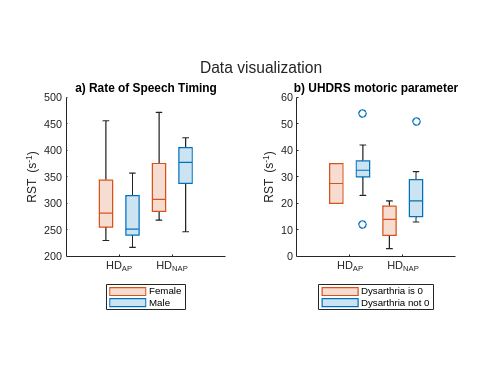

title(tl, "Data visualization")
ax1 = nexttile;

xgroup = categorical(T.group, {'HD_AP', 'HD_NAP'});

boxchart(xgroup, T.RST,'GroupByColor',T.gender);
set(gca, 'XTickLabel', {'HD_{AP}', 'HD_{NAP}'})
colororder([0.8500 0.3250 0.0980;0 0.4470 0.7410])
title('a) Rate of Speech Timing'); ylabel('RST (s^{-1})')
pbaspect(ax1,[1 1 1]);
legend("Female", "Male", "Location","southoutside")

ax2 = nexttile;

xgroup = categorical(T.group, {'HD_AP', 'HD_NAP'});

boxchart(xgroup, T.motor,'GroupByColor',T.dysarthria ~= 0);
set(gca, 'XTickLabel', {'HD_{AP}', 'HD_{NAP}'})
title('b) UHDRS motoric parameter'); ylabel('RST (s^{-1})')
pbaspect(ax2,[1 1 1]);
legend("Dysarthria is 0", "Dysarthria not 0", "Location","southoutside")

## 2. Analýza 1

V této úloze je vizualizace dat zcela dobrovolná a nebude hodnocena, nicméně ji samozřejmě zcela doporučujeme zejména k lepšímu porozumění pozorovaných efektů.

**Na následující dvě otázky odpovězte pomocí jediného testu.**

- *Mají pacienti s HN beroucí antipsychotickou medikaci statisticky významně změněnou rychlost řeči oproti pacientům, kteří antipsychotika neberou?*

- *Lze pozorovat statisticky významné změny v rychlosti řeči způsobené antipsychotickými léky specificky (pouze) pro jedno z pohlaví?*

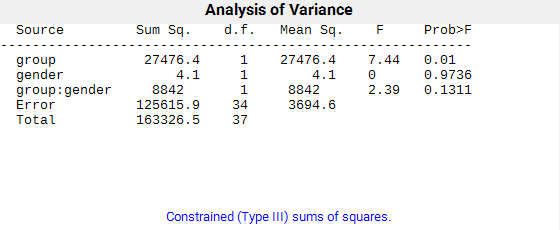

% Analýza
alpha = 0.05;
genders = ["F", "M"];
groups = ["AP", "NAP"];
res = table('Size',[0, 4], 'VariableTypes', ["string","string", "string", "logical"], 'VariableNames', ["Group", "Gender", "SW test report", "Is normal"]);

for gender = genders
    for group = groups
        [h, p, stat] = swtest(T{all([string(T.gender)==gender, string(T.group)==sprintf("HD_%s", group)],2), "RST"}, alpha);
        res = [res; {group, gender, sprintf('swtest(W = %.2f, p = %.2f)',stat, p), ~h}];
    end
end

p12 = anovan(T.RST, {T.group, T.gender}, 'model','full','varnames',{'group', 'gender'}, 'alpha',alpha);

**Následující otázku musíte řešit testem zvlášť od prvních dvou.**

         3. *Pokud bychom brali hodnocení stavu motoriky na škále UHDRS jako nezávislý kovariát (spojitý faktor), jaký bude mít vliv                 na výsledky z první otázky?*

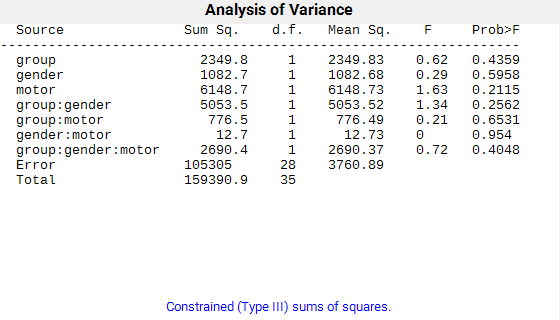

% Analýza
p3 = anovan(T.RST, {T.group, T.gender, T.motor}, 'continuous', 3, 'model','full','alpha',alpha, 'varnames', {'group', 'gender', 'motor'});

U otázek v této i následující části si dejte záležet na korektním provedení testu a intepretaci výsledků.

- Testování normality/homoskedasticity vám dá informaci o tom, jak budou výsledky ovlivněné chybou I. typu, pokud vstupní data nebudou normální, protože zde není možnost použít neparametrickou metodu pro více-faktorové testování.

- Výsledky, jako vždy, korektně reportujte.

#### Vaše odpovědi a výsledky:

1.

    F(1, 34) = 7.44, p = .01

    Pacienti, kteří berou antipsychotika, nemají významně změněné RST oproti pacientům bez antipsychotik.

2.

    F(1, 34) = 2.39, p = .1311

    Nelze vyloučit, že pacienti jednoho pohlaví mají významné změny v RST mezi skupinami pobírajícími antipsychotika a nepobírajícími antipsychotika.

3.

    F(1, 28) = 0.21, p = .6531

    F(1, 28) = 0.72, p = .4048

    Spojitá proměnná motor výrazně ovlivuje výsledek otázek 1. a 2. U obou otázek lze odpovědět s výrazně vyšší jistotou, že antipsychotika mají vliv na RST.

## 3. Analýza 2

Rozdělme si pacienty na ty s postiženou řečí a ty bez postižené řeči – to můžeme provést na základě klinického hodnocení řeči skrytého pod položkou dysarthria, kde hodnota 0 znamená nepostiženou řeč, všechny ostatní hodnoty pak řeč (různě) postiženou.

*Mají pacienti s poruchou řeči ve srovnání s pacienty bez poruchy řeči významně zhoršené hodnoty motorického hodnocení UHDRS, pokud budeme brát v potaz i vliv toho, jestli berou antipsychotika, nebo ne?*

% Analýza
dysarthria = T.dysarthria ~= 0;

res = table('Size',[0, 4], 'VariableTypes', ["logical","string", "string", "logical"], 'VariableNames', ["Has speech impedament", "Group", "SW test report", "Is normal"]);

for i=[0,1]
    for group=groups
        data = T{all([dysarthria == i, string(T.group)==sprintf("HD_%s", group)],2), "motor"};
        if length(data) > 2
            [h, p, stat] = swtest(data, alpha);
            res = [res; {i, group, sprintf('swtest(W = %.2f, p = %.2f)',stat, p), ~h}];
        else
            res = [res; {i, group, NaN, 1}];
        end
    end
end

disp(res)

    Has speech impedament    Group           SW test report           Is normal
    _____________________    _____    ____________________________    _________

              0              "AP"     <missing>                           1    
              0              "NAP"    "swtest(W = 0.91, p = 0.45)"        1    
              1              "AP"     "swtest(W = 0.89, p = 0.04)"        0    
              1              "NAP"    "swtest(W = 0.84, p = 0.05)"        0    



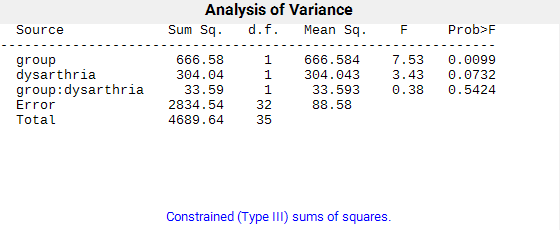


p = anovan(T.motor, {T.group, dysarthria}, "alpha",alpha, "model","full","varnames",{'group', 'dysarthria'});

#### Vaše odpovědi a výsledky:

F(1, 32) = 0.38, p = .54

Je pravděpodobné, že pacienti s poruchou řeči mají i významně zhoršené hodnoty motorického hodnocení UHDRS.